# 4QZ3 - Modelling: A2 - suitorj - 400138679

## Question 1

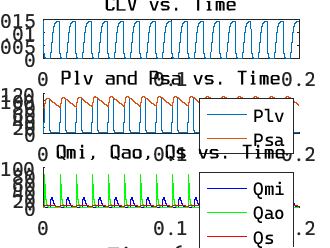

Q1_init;
q1_out = sim("q1_model");

figure;
subplot(3, 1, 1);
plot(q1_out.clv.Time, q1_out.clv.Data)
title("CLV vs. Time")
ylim([0 .015])
yticks([0, 0.005, 0.01, 0.015])
xlabel("Time (min)" + newline + " ")
ylabel("CLV" + newline + "(L/mmHg)")

subplot(3, 1, 2);
hold on
plot(q1_out.plv_psa.Time, q1_out.plv_psa.Data(:, 1))
plot(q1_out.plv_psa.Time, q1_out.plv_psa.Data(:, 2))
title("Plv and Psa vs. Time")
ylim([0 120])
yticks([0, 20, 40, 60, 80, 100, 120])
legend("Plv", "Psa")
xlabel("Time (min)" + newline + " ")
ylabel("Plv and Psa" + newline + "(mmHg)")

subplot(3, 1, 3);
hold on
plot(q1_out.qmi_qao_qs.Time, q1_out.qmi_qao_qs.Data(:, 1), 'Color', 'b')
plot(q1_out.qmi_qao_qs.Time, q1_out.qmi_qao_qs.Data(:, 2), 'Color', 'g')
plot(q1_out.qmi_qao_qs.Time, q1_out.qmi_qao_qs.Data(:, 3), 'Color', 'r')
hold off
title("Qmi, Qao, Qs vs. Time")
legend("Qmi", "Qao", "Qs")
ylim([0 100])
yticks([0, 20, 40, 60, 80, 100])
xlim([0 0.2])
xlabel("Time (min)")
ylabel("Blood Flows" + newline + "(L/mmHg)")

- Integrator for Psa was set to Psai * Csa because the integrator is immediately divided by Csa.

- The function for CLV(t) was taken from the provided supplementary material chapter.

- The integrator for Plv was initially set to Plvi.

### Question 2

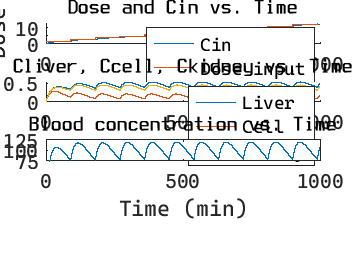

q2_out = sim("q2_model");

figure;
subplot(4, 1, 1)
hold on
plot(q2_out.Cin)
plot(q2_out.dose)
hold off
legend("Cin", "Dose input")
ylabel("Dose")
xlabel("Time (min)" + newline + " ")
title("Dose and Cin vs. Time")

subplot(4, 1, 2)
hold on
plot(q2_out.Cout.Time, q2_out.Cout.Data(:, 1))
plot(q2_out.Cout.Time, q2_out.Cout.Data(:, 2))
plot(q2_out.Cout.Time, q2_out.Cout.Data(:, 3))
hold off
legend("Liver", "Cell", "Kidney")
ylabel("Con.")
xlabel("Time (min)" + newline + " ")
title("Cliver, Ccell, Ckidney vs. Time")

subplot(4, 1, 3)
plot(q2_out.Cout_tot)
ylim([75 125])
yticks([75, 100, 125])
ylabel("Dose (%)")
xlabel("Time (min)")
title("Blood concentration vs. Time")

- Initially a 1.75 dose is given and then 90 minutes afterwards another single dose is given.

- This dose is absorbed in the gut with a 15 minute drug half life.

- The dose that has entered is then assumed to be evenly split among the 3 excretory systems.

- In each subsystem the input is reduced and exported.

- The exported value of the three subsystems is summed together which represents the current concentration in the blood. This is because any drug that is absorbed but has not been excreted is contained within the system. Due to modelling the process in this way the process is uncontrolled and to represent a new dose the input signal must increment and remain incremented to create the desired conditions.

- The concentration in the blood is not constant with time as seen in the above figure however, the dose dose eventually reach steady state.

- Another assumption is that the time constants remain the same and do not change.